## **QIBC analysis of cells treated with MLN-4924 (with siRNA) **

**Variables:**

normGem = normalized mean APC/C reporter  intensity within nucleus

**FarRed1** = normalized mean EdU  intensity within nucleus

**Cy31** = normalized mean IF stain  intensity within nucleus

**CDK2** = normalized cytoplasmic:nuclear ratio of Cyclin E/A-CDK reporter

## Load data

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

conditions = {
    'siCtrl DMSO',1:3,3,1:25,'siCtrl','DMSO'; 
    'siCtrl MLN',4:6,3,1:25,'siCtrl','MLN';
    
    'siGMNN DMSO',1:3,4,1:25,'siGMNN','DMSO';
    'siGMNN MLN',4:6,4,1:25,'siGMNN','MLN';
    
    'siCdt1 DMSO',1:3,5,1:25,'siCdt1','DMSO';
    'siCdt1 MLN',4:6,5,1:25,'siCdt1','MLN';
    
    'siP21 DMSO',1:3,6,1:25,'siP21','DMSO';
    'siP21 MLN',4:6,6,1:25,'siP21','MLN';
    
    'siP27 DMSO',1:3,7,1:25,'siP27','DMSO';
    'siP27 MLN',4:6,7,1:25,'siP27','MLN';
    
    'siSet8 DMSO',1:3,8,1:25,'siSet8','DMSO';
    'siSet8 MLN',4:6,8,1:25,'siSet8','MLN';
    
    'siCdt1/GMNN DMSO',1:3,9,1:25,'siCdt1/GMNN','DMSO';
    'siCdt1/GMNN MLN',4:6,9,1:25,'siCdt1/GMNN','MLN';
    
    'siP21/GMNN DMSO',1:3,10,1:25,'siP21/GMNN','DMSO';
    'siP21/GMNN MLN',4:6,10,1:25,'siP21/GMNN','MLN';
    
    'siP27/GMNN DMSO',1:3,11,1:25,'siP27/GMNN','DMSO';
    'siP27/GMNN MLN',4:6,11,1:25,'siP27/GMNN','MLN';
    
    'siSet8/GMNN DMSO',1:3,12,1:25,'siSet8/GMNN','DMSO';
    'siSet8/GMNN MLN',4:6,12,1:25,'siSet8/GMNN','MLN';
    
    'Geminin DMSO',1,1,1:25,'Geminin','DMSO';
    'Geminin MLN',4,1,1:25,'Geminin','MLN';

    'Cdt1 DMSO',1,2,1:25,'Cdt1','DMSO';
    'Cdt1 MLN',4,2,1:25,'Cdt1','MLN';
    
    'p21 DMSO',2,1,1:25,'p21','DMSO';
    'p21 MLN',5,1,1:25,'p21','MLN';

    'p27 DMSO',2,2,1:25,'p27','DMSO';
    'p27 MLN',5,2,1:25,'p27','MLN';
    
    'Set8 DMSO',3,1,1:25,'p27','DMSO';
    'Set8 MLN',6,1,1:25,'p27','MLN';
   


};
load([dataDir 'E1090_data.mat'],'S');
% S = loaddata_E1090(conditions, dataDir);



## Plot to take a look at measurements

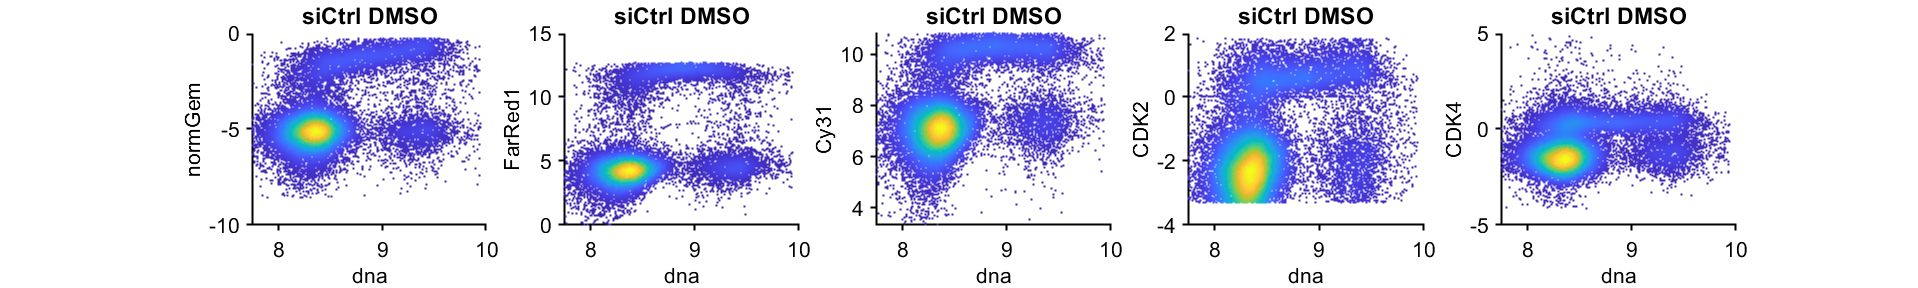

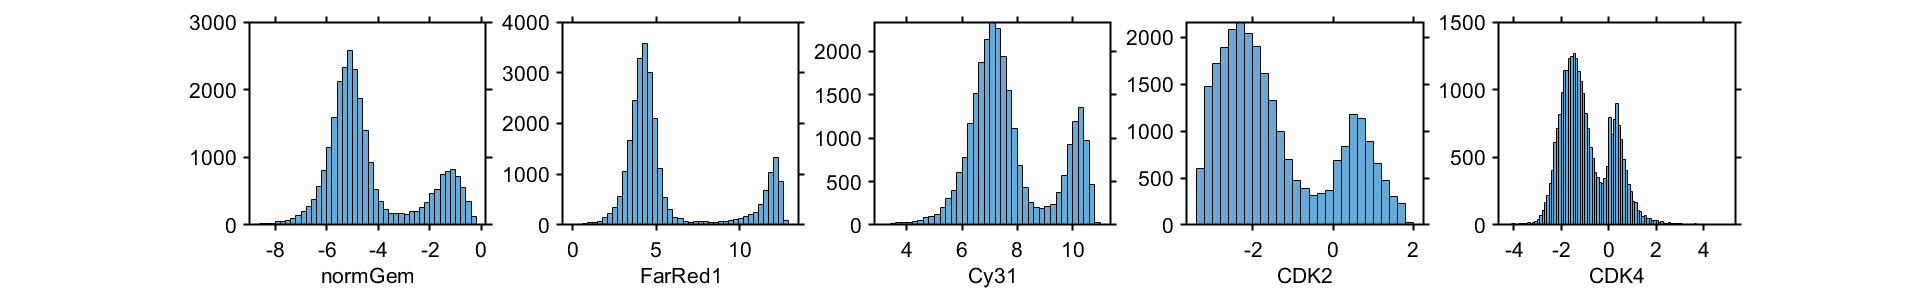

conds = [1];

xval = {'dna','dna','dna','dna','dna'};
%xbg = [xval 'bg'];
yval = {'normGem','FarRed1','Cy31','CDK2','CDK4'};
%ybg = [yval 'bg'];

gateVals = {};
rangeVals = {};

for i = 1:length(conds)    
    f1 = figure('pos',[0 0 length(xval)*400 300]);
    f2 = figure('pos',[0 0 length(xval)*400 300]);
    for s = 1:length(xval)
        condition = conds(i);
        xdata = log2(S(condition).(xval{s}));
        ydata =  log2(S(condition).(yval{s}));
        
        totalGate = true(size(xdata,1),1);
        for gate = 1:size(gateVals,2)
            gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
            totalGate = totalGate  & gateInds;
        end
        
        xdata = xdata(totalGate);
        ydata = ydata(totalGate);
        xmin = prctile(xdata,.5); xmax = prctile(xdata,99.5);
        ymin = prctile(ydata,.5); ymax = prctile(ydata,99.5);
        ind = xdata>xmin & xdata<xmax & ydata>ymin & ydata<ymax;
        xdata = xdata(ind); ydata = ydata(ind);
        
        figure(f1);
        subplot(1, length(xval),s)
        dscatter(xdata,ydata);
        ylabel(yval{s});xlabel(xval{s});
        title(conditions{condition,1});
        figure(f2);
    subplot(1, length(xval),s)
        histogram(ydata)
        xlabel(yval{s})
        
    end
end

## Cdt1 vs APC for different conditions

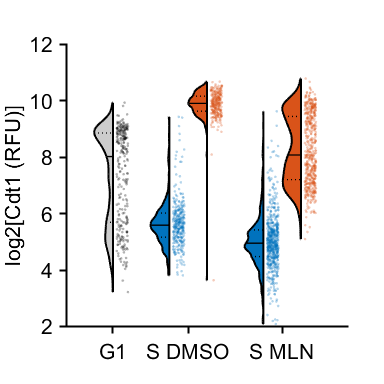

rng(1)

%conds = [1:4];
cond_g1 = 23;
cond_S = [23 24 5 6];
yval = 'Cy31';
ally = [];
group= [];
gind = 1;
%G1 
conds=cond_g1;
gateVals = {'dna','CDK4','normGem','CDK2','FarRed1'};
rangeVals = {[2^7.8 2^8.7],[0 Inf],[0 .125],[.5 .8],[0 2^5]}; 
for i=1:length(conds)
        
    condition=conds(i);
    ydata =  log2(S(condition).(yval));
    totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
    ydata = ydata(totalGate);
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end

%S phase
conds=cond_S;
gateVals = {'dna','CDK4','normGem','CDK2'};
rangeVals = {[2^7.8 2^8.7],[0 Inf],[.15 .25],[.8 Inf]}; 
for i=1:length(conds)
        
    condition=conds(i);
    ydata =  log2(S(condition).(yval));
    totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
    ydata = ydata(totalGate);
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],...
    'xNames',{'G1','siCtrl S DMSO','siCtrl S MLN','siCdt1 S MLN','siCdt1 S MLN'},'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
% cols = [14 113 186; 193 39 45]/255;
cols = lines(2);
groupcol = [[0 0 0];cols([1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('log2[Cdt1 (RFU)]')
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','S DMSO','S MLN'})
% hline(8)
% ylim([0 2.25])
% xtickangle(45)
axis square
print_pdf([pwd() '\Figs\Cdt1_scatter.pdf'])

num_cells = splitapply(@length,ally,group)

num_cells =    272
   324
   279
   603
   544


## p21 vs APC for different conditions

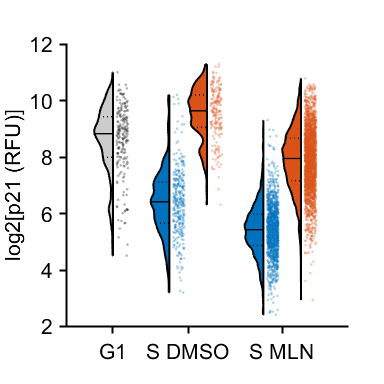

rng(1)

cond_g1 = 23+2;
cond_S = [23 24 5 6]+2;
yval = 'Cy31';
ally = [];
group= [];
gind = 1;
%G1 
conds=cond_g1;
gateVals = {'dna','CDK4','normGem','CDK2','FarRed1'};
rangeVals = {[2^7.8 2^8.7],[0 Inf],[0 .125],[.5 .8],[0 2^5]}; 
for i=1:length(conds)
        
    condition=conds(i);
    ydata =  log2(S(condition).(yval));
    totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
    ydata = ydata(totalGate);
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end

%S phase
conds=cond_S;
gateVals = {'dna','CDK4','normGem','CDK2'};
rangeVals = {[2^7.8 2^8.7],[0 Inf],[.15 .25],[.8 Inf]}; 
for i=1:length(conds)
        
    condition=conds(i);
    ydata =  log2(S(condition).(yval));
    totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
    ydata = ydata(totalGate);
    ydata = ydata(ydata < 12 & ydata  >2); % remove random really high/low cell
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],...
    'xNames',{'G1','siCtrl S DMSO','siCtrl S MLN','siCdt1 S MLN','siCdt1 S MLN'},'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
% cols = [14 113 186; 193 39 45]/255;
cols = lines(2);
groupcol = [[0 0 0];cols([1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('log2[p21 (RFU)]')
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','S DMSO','S MLN'})
% hline(8)
% % ylim([0 2.25])
% xtickangle(45)
axis square
print_pdf([pwd() '\Figs\p21_scatter.pdf'])

num_cells = splitapply(@length,ally,group)

num_cells =          204
         332
         202
        1396
        2625


## geminin vs APC for different conditions

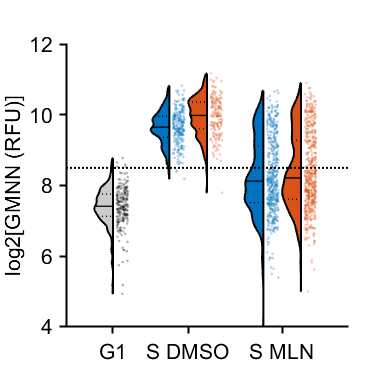

rng(1)

cond_g1 = 23-2;
cond_S = [23 24 5 6]-2;
yval = 'Cy31';
ally = [];
group= [];
gind = 1;
%G1 
conds=cond_g1;
gateVals = {'dna','CDK4','normGem','CDK2','FarRed1'};
rangeVals = {[2^7.8 2^8.7],[0 Inf],[0 .125],[.5 .8],[0 2^5]}; 
for i=1:length(conds)
        
    condition=conds(i);
    ydata =  log2(S(condition).(yval));
    totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
    ydata = ydata(totalGate);
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end

%S phase
conds=cond_S;
gateVals = {'dna','CDK4','normGem','CDK2'};
rangeVals = {[2^7.8 2^8.7],[0 Inf],[.15 .25],[.8 Inf]}; 
for i=1:length(conds)
        
    condition=conds(i);
    ydata =  log2(S(condition).(yval));
    totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
    ydata = ydata(totalGate);
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],...
    'xNames',{'G1','siCtrl S DMSO','siCtrl S MLN','siCdt1 S MLN','siCdt1 S MLN'},'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
% cols = [14 113 186; 193 39 45]/255;
cols = lines(2);
groupcol = [[0 0 0];cols([1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('log2[GMNN (RFU)]')
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','S DMSO','S MLN'})
hline(8.5,'k:')
% ylim([0 2.25])
% xtickangle(45)
axis square
print_pdf([pwd() '\Figs\gmnn_scatter.pdf'])


num_cells = splitapply(@length,ally,group)

num_cells =    205
   243
   174
   487
   558


## EdU vs APC

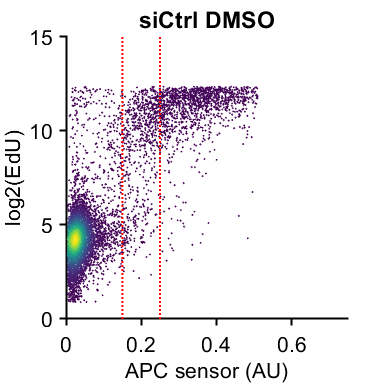

rng(1)
conds=[1];
%conds = [1:4];
xval = 'normGem';
yval = 'FarRed1';
cval = 'FarRed1';

gateVals = {'dna','CDK4','normGem'};
rangeVals = {[2^7.8 2^8.7],[0 Inf],[0 .8]}; 

% norm=24;
[rows,cols]=size(conds);
figure('units','inches','pos',[0 0 4*length(conds) 4])

% standx=([prctile(S(norm).(xval),1) prctile(S(norm).(xval),99)]);
% standy=([prctile(S(norm).(yval),1) prctile(S(norm).(yval),99)]);


for i=1:rows
    for j=1:cols
    condition=conds(i,j);
    xdata = (S(condition).(xval));
    ydata =  log2(S(condition).(yval));
    cdata = log2(S(condition).(cval));

    totalGate = true(size(xdata,1),1);
    
    for gate = 1:length(gateVals)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    xdata = xdata(totalGate);
    ydata = ydata(totalGate);
    cdata = cdata(totalGate);
    
    ind = ydata<prctile(ydata,99)&xdata<prctile(xdata,99)&ydata>prctile(ydata,1)&xdata>prctile(xdata,1);
    
    xdata = xdata(ind);
    ydata = ydata(ind);
    cdata = cdata(ind);
    
    subplot(rows,cols,j+cols*(i-1))
    %     scatter(xdata,ydata,[],cdata,'.');
    colormap('viridis')
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o')
%     colormap parula
%     caxis([6 12]);

    xlim([0 .75]);
%     ylim([4 11]);
    ylabel('log2(EdU)');
    xlabel('APC sensor (AU)');
    title(conditions{condition,1});
    axis square
        vline([.15 .25])
%     set(gca,'FontSize',8)

    end
end
print_pdf([pwd() '\Figs\edu_scatter.pdf'])

## geminin vs APC for different conditions

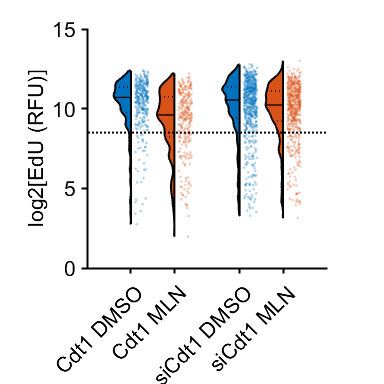

rng(1)

% cond_g1 = 23-2;
cond_S  = [23 24 5 6];
yval = 'FarRed1';
ally = [];
group= [];
gind = 1;
% %G1 
% conds=cond_g1;
% gateVals = {'dna','CDK4','normGem','CDK2','FarRed1'};
% rangeVals = {[2^7.8 2^8.7],[0 Inf],[0 .125],[.5 .8],[0 2^5]}; 
% for i=1:length(conds)
%         
%     condition=conds(i);
%     ydata =  log2(S(condition).(yval));
%     totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
%     ydata = ydata(totalGate);
%     ally = [ally; ydata];
%     
%     group = [group; gind*ones(size(ydata)) ];
%     gind = gind + 1;
% end

%S phase
conds=cond_S;
gateVals = {'dna','CDK4','normGem','CDK2'};
rangeVals = {[2^7.8 2^8.7],[0 Inf],[.15 .25],[.8 Inf]}; 
for i=1:length(conds)
        
    condition=conds(i);
    ydata =  log2(S(condition).(yval));
    totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
    ydata = ydata(totalGate);
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end
groups = 1:max(group);
offsetx = floor((groups - 1)/2) * .5;
xkey = groups + offsetx;

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],...
    'xNames',conditions(conds,1),'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
% cols = [14 113 186; 193 39 45]/255;
cols = lines(2);
groupcol = [cols([1 2 1 2],:)];
set(h{1},{'FaceColor'},{cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('log2[EdU (RFU)]')
% xticks([1 xkey(2:2:length(xkey)-1)+.5])
% xticklabels({'G1','S DMSO','S MLN'})
hline(8.5,'k:')
% ylim([0 2.25])
xtickangle(45)
axis square

% print_pdf([pwd() '\Figs\gmnn_scatter.pdf'])

num_cells = splitapply(@length,ally,group)

num_cells =    324
   279
   603
   544


Load data

conds = [1:30];

gateVals = {'dna','CDK2','CDK4','normGem','FarRed1'};
rangeVals = {[2^7.5 2^8.7],[.8 100],[0 100],[.15 .25],[2^0 Inf]}; 

ydata_all = [];
well_all = [];
cond_num_all = [];
cond_name_all = [];
drug_all = [];
sirna_all = [];
stain_all = [];
for j = 1:length(conds)
    condition = conds(j);
    ydata =  S(condition).FarRed1;
    well = S(condition).well_ID;
    staindata = S(condition).Cy31;
    totalGate = true(size(ydata,1),1);
    
    for gate = 1:length(gateVals)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    well = well(totalGate);
    cond_num = repmat(condition,size(ydata));
    cond_name = repmat(string(conditions(condition,1)),size(ydata));
    drug = repmat(string(conditions(condition,6)),size(ydata));
    sirna = repmat(string(conditions(condition,5)),size(ydata));
    staindata = staindata(totalGate); 
    
    ydata_all = [ydata_all; ydata];
    well_all = [well_all; string(well)];
    cond_num_all = [cond_num_all; cond_num];
    cond_name_all = [cond_name_all; cond_name];
    sirna_all = [sirna_all; sirna];
    drug_all = [drug_all; drug];
    stain_all = [stain_all; staindata];
end

df = table(categorical(cond_name_all),cond_num_all,categorical(well_all),categorical(sirna_all),categorical(drug_all),ydata_all, stain_all);
df.Properties.VariableNames = {'cond','c_ind','well','sirna','drug','edu','stain'};

wellsize = wellsize(:,:,1) =

   211   218
   179   181
   464   898
   103   110
   129    95
   346   697


wellsize(:,:,2) =

   216   247
   208   202
   454   903
   102    92
   127    96
   365   633


wellsize(:,:,3) =

   201   274
   211   157
   486   840
   100   134
   125   136
   379   678


ans = 92

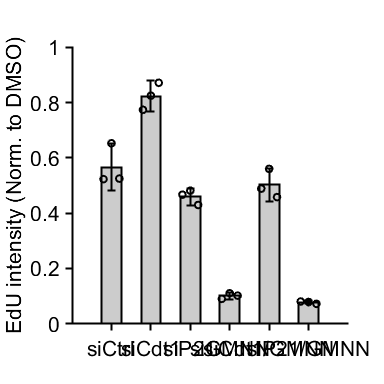

h =    NaN     1     0     1     0     1
     1   NaN     1     1     1     1
     0     1   NaN     1     0     1
     1     1     1   NaN     1     0
     0     1     0     1   NaN     1
     1     1     1     0     1   NaN


p =        NaN    0.0365    0.0859    0.0066    0.0619    0.0073
    0.0365       NaN    0.0121    0.0012    0.0204    0.0017
    0.0859    0.0121       NaN    0.0018    0.1386    0.0012
    0.0066    0.0012    0.0018       NaN    0.0045    0.0795
    0.0619    0.0204    0.1386    0.0045       NaN    0.0046
    0.0073    0.0017    0.0012    0.0795    0.0046       NaN


colors = {[.5 .5 .5], [.8 .8 .8]};

sirnas = {'siCtrl','siCdt1','siP21','siGMNN','siCdt1/GMNN','siP21/GMNN'};
drugs = {'DMSO','MLN'};
% stain_threshs = [Inf 2^8.5 2^8 2^8];
stain_threshs = [Inf  Inf Inf 2^8.5 2^8.5 2^8.5];

[h,p] = plot_groups(df, colors, drugs, stain_threshs, sirnas,'all',false)

function plotEdU_APC(S, conds, xval,y1val,thresh,gateVals,rangeVals,plotCodes,colorCodes,numbins, range, colors,conditions)
figure('pos',[10 10 400 600])
hold on
for i = 1:length(conds)
    condition = conds(i);
    xdata = (S(condition).(xval));
    y1data =  log2(S(condition).(y1val));
    
    totalGate = true(size(xdata,1),1);
    
    for gate = 1:length(gateVals)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    xdata = xdata(totalGate);
    y1data = y1data(totalGate);
    
    [~,bins] = histc(xdata,range);
    binmed1 = [];
    binperc1 = [];
    binmedpos1 = [];
    binpercerr1 = [];
    for n  =  1:(numbins)
        bindata  = y1data(bins  ==  n);
        binmed1(n) = median(bindata);
        binperc1(n) = sum(bindata > thresh)/length(bindata);
        binmedpos1(n) = median(bindata(bindata > thresh));
        binpercerr1(n) = sqrt(binperc1(n)*(1-binperc1(n))/length(bindata));
    end
    subplot(2,1,1), hold on
    errorbar(range,binperc1,2*binpercerr1,plotCodes{i}(1:end-1),'LineWidth',1,'Color',colors(colorCodes(i),:))
    ylim([0 1]);
    ylabel('Percent EdU pos');
    xlabel('APC degron levels (AU)');
    
    
    subplot(2,1,2), hold on
    plot(range,binmed1,plotCodes{i},'Color',colors(colorCodes(i),:),'MarkerFaceColor',colors(colorCodes(i),:))
    ylabel('Median EdU');
    xlabel('APC degron levels (AU)');
    
end
subplot(2,1,1)
legend(conditions(conds,1));
set(findall(gcf,'-property','FontSize'),'FontSize',12)
set(gca,'linewidth',1)
set(findall(gca, 'Type', 'Line'),'LineWidth',1);
subplot(2,1,2)
legend(conditions(conds,1));
set(findall(gcf,'-property','FontSize'),'FontSize',12)
set(gca,'linewidth',1)
set(findall(gca, 'Type', 'Line'),'LineWidth',1);
end

function plotEdU_APC_err(S, conds, xval,y1val,thresh,gateVals,rangeVals,plotCodes,colorCodes,numbins, range, colors,conditions)
figure('pos',[10 10 400 600])
hold on
for i = 1:length(conds)
    condition = conds(i);
    xdata = (S(condition).(xval));
    y1data =  log2(S(condition).(y1val));
    
    totalGate = true(size(xdata,1),1);
    
    for gate = 1:length(gateVals)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    xdata = xdata(totalGate);
    y1data = y1data(totalGate);
    
    [~,bins] = histc(xdata,range);
    binmed1 = [];
    binperc1 = [];
    binmedpos1 = [];
    binpercerr1 = [];
    bincerr1 = [];
    for n  =  1:(numbins)
        bindata  = y1data(bins  ==  n);
        binmed1(n) = median(bindata);
        binperc1(n) = sum(bindata > thresh)/length(bindata);
        binmedpos1(n) = median(bindata(bindata > thresh));
        binpercerr1(n) = sqrt(binperc1(n)*(1-binperc1(n))/length(bindata));
        bincerr1(n) = std(bindata)/sqrt(length(bindata));
    end
    subplot(2,1,1), hold on
    errorbar(range,binperc1,2*binpercerr1,plotCodes{i}(1:end-1),'LineWidth',1,'Color',colors(colorCodes(i),:))
    ylim([0 1]);
    ylabel('Percent EdU pos');
    xlabel('APC degron levels (AU)');
    
    
    subplot(2,1,2), hold on
    errorbar(range,binmed1,2*bincerr1,plotCodes{i}(1:end-1),'Color',colors(colorCodes(i),:),'MarkerFaceColor',colors(colorCodes(i),:))
    ylabel('Median EdU');
    xlabel('APC degron levels (AU)');
    
end
subplot(2,1,1)
legend(conditions(conds,1));
set(findall(gcf,'-property','FontSize'),'FontSize',12)
set(gca,'linewidth',1)
set(findall(gca, 'Type', 'Line'),'LineWidth',1);
subplot(2,1,2)
legend(conditions(conds,1));
set(findall(gcf,'-property','FontSize'),'FontSize',12)
set(gca,'linewidth',1)
set(findall(gca, 'Type', 'Line'),'LineWidth',1);
end

function [h,p]=plot_groups(df, colors, drugs, stain_threshs, sirnas, name, ind_compare)
temp = rowfun(@(v) numel(unique(v)), df, 'GroupingVariables','c_ind','InputVariables','well');
maxwells = max(temp.Var3);
wellmeans = NaN * ones(length(sirnas),length(drugs),maxwells);
wellmedians = NaN * ones(length(sirnas),length(drugs),maxwells);
wellsize= NaN * ones(length(sirnas),length(drugs),maxwells);

means =  NaN * ones(length(sirnas),length(drugs));
sems =  NaN * ones(length(sirnas),length(drugs));

all_data = {};
for s = 1:length(sirnas)
    for d = 1:length(drugs)
        subdf = df(df.sirna == sirnas{s} & df.drug == drugs{d}, :);
        subdf = subdf(subdf.stain < stain_threshs(s),:);
        data = subdf.edu;
        wells = subdf.well;
        groups = findgroups(wells);
        
        means(s,d) = mean(data);
        sems(s,d) = std(data)/sqrt(length(data));
        
        wellmeans(s,d,:) = splitapply(@mean, data, groups);
        wellmedians(s,d,:) = splitapply(@median, data, groups);
        wellsize(s,d,:) = splitapply(@length, data, groups);
        
        all_data{s,d} = log2(data);
        
    end
end 

wellmeanmean = mean(wellmeans,3);
wellmeansem = std(wellmeans,[],3)/sqrt(size(wellmeans,3));

wellmedmean = mean(wellmedians,3);
wellmedsem = std(wellmedians,[],3)/sqrt(size(wellmedians,3));

norm_wellmedians = wellmedians ./ wellmedmean(:,1);
norm_wellmedmean = mean(norm_wellmedians,3);
norm_wellmedsem = std(norm_wellmedians,[],3)/sqrt(size(norm_wellmedians,3));
wellsize
min(wellsize(:))
figure('units','inches','position',[0 0 4 4])
hBar = bar(1:length(sirnas), norm_wellmedmean(:,2),.5,'FaceColor',colors{2},'EdgeColor','k','LineWidth',1.5);
box off
axis square

offsets = [hBar.XOffset];
set(gca,'XTickLabel',sirnas);
% xtickangle(45);
xlim([0 length(sirnas)+1])

xvals = [1:length(sirnas)]';
yvals = squeeze(norm_wellmedians(:,2,:));
xval_rep = repmat(xvals,1,size(yvals,2));
hold on
errorbar(1:length(sirnas), norm_wellmedmean(:,2)', 2*norm_wellmedsem(:,2)', '+k','LineWidth',1.5)
jit = .2*linspace(-1,1,size(yvals,2));
xval_rep_jit = xval_rep + jit;
scatter(xval_rep_jit(:),yvals(:),25,'k','LineWidth',1.5)
hold off
ylabel('EdU intensity (Norm. to DMSO)');
print_pdf([pwd() '\Figs\comparenorm_' name '.pdf'])

% [p,t,stats] = anova1(yvals(:),xval_rep(:));
% c = multcompare(stats);
h = [];
p = [];
groups = unique(xval_rep);
for i = 1:length(groups)
    for j = 1:length(groups)
        x1 = yvals(xval_rep == groups(i));
        x2 = yvals(xval_rep == groups(j));
        [h(i,j), p(i,j)] = ttest(x1(:),x2(:),'Alpha',0.05,'Tail','both');
    end
end

end